T = 0.005;
K1 = 85;
T1 = 0.09;
K2 = 70;
T2 = 0.1;
K3 = 0.02;
tn = 0.165;
sigma = 10;

A_cont = [0 0.02 0; 0 -10 700; 0 0 -11.1];
B_cont = [0 0 944.4]';
C = [1 0 0];
A_dsc = expm(A_cont*T)

A_dsc =     1.0000    0.0001    0.0002
         0    0.9512    3.3202
         0         0    0.9460


B_dsc = zeros([3 1]);
for i = 1:100
    B_dsc = B_dsc + T^i*A_cont^(i-1)/factorial(i);
end
B_dsc = B_dsc*B_cont

B_dsc =     0.0003
    7.9786
    4.5934


save('data.mat')

W_dsc_coefs = [0 26.8*10^-3 0.00105 0.255*10^-3;
               1 -2.9 2.8 -0.9];

Tmdl = 1;

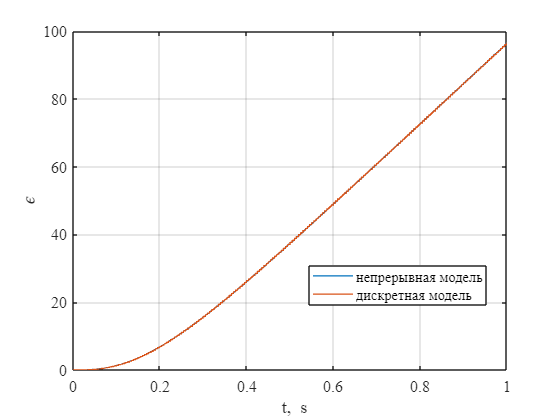

warning off
SimNew = sim('model.slx','ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.y.time;
y_cont = SimNew.y.signals.values(:, 1);
y_dsc = SimNew.y.signals.values(:, 2);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,y_cont,'LineWidth',1)
hold on
grid on
plot(t,y_dsc,'LineWidth',1)
xlim([0 Tmdl])
xlabel('\it t\rm,\it s')
ylabel('\epsilon')
legend('непрерывная модель', 'дискретная модель','Location','best')

tn_star = 6.0;
omega0 = tn_star/tn

omega0 = 36.3636

GH = [-18.18 31.4887 0; -31.4887 -18.18 0; 0 0 -36.36];
H = [1 0 1];
G = expm(GH*T)

G =     0.9018    0.1432         0
   -0.1432    0.9018         0
         0         0    0.8338


M = sylvester(-A_dsc,G,-B_dsc*H)

M = 1.0e+03 *

   -0.0003   -0.0002    0.0006
    0.5595   -0.3471   -1.0888
    0.0090    0.0293    0.0409


K = H*inv(M)

K =     3.1948    0.0028    0.0516


eig(G)

ans =    0.9018 + 0.1432i
   0.9018 - 0.1432i
   0.8338 + 0.0000i


eig(A_dsc-B_dsc*K)

ans =    0.9018 + 0.1432i
   0.9018 - 0.1432i
   0.8338 + 0.0000i


Tmdl = 1;

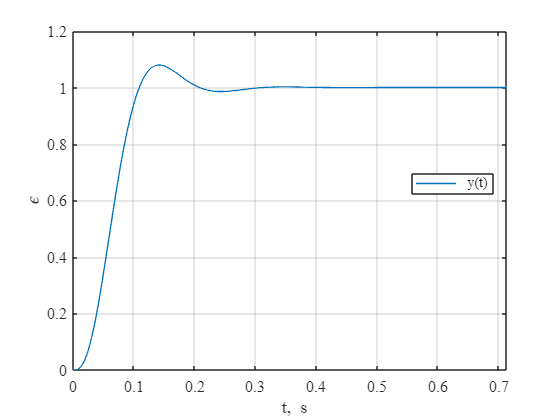

warning off
SimNew = sim('model_reg.slx','ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.y.time;
y_cont = SimNew.y.signals.values(:, 1);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,y_cont,'LineWidth',1)
hold on
grid on
xlim([0 Tmdl/2])
xlabel('\it t\rm,\it s')
ylabel('\epsilon')
legend('\it y(t)','Location','best')

wd = y_cont

wd =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


% Время переходного процесса tp1 (5% зона)
t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.3f \n',ttr5)

Время переходного процесса tp1 для 5% зоны: 0.101 


% Время переходного процесса tp2 (5% зона)
D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.3f \n',ttr5)

Время переходного процесса tp2 для 5% зоны: 0.171 


% Перерегулирование
dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.3f%%\n',dy*100)

Перерегулирование: 7.970%
